# **Задание 3_3**

## **Требуется:**

Построить график **fplot** и найти графически корень нелинейного уравнения

*                                                            f*(*x*) = 0

на заданном отрезке. Найти численное решение уравнения, используя решатели** fzero** и **fsolve.** Функцию задавать с помощью дескриптора @.

figure('Name', 'ROOT', 'NumberTitle', 'off');
hold on;
grid on;
fun = @(x) x.^4 + 2*x.^3 - x - 1;
fplot(fun, [-10 10]);
title('Корень уравнения');
xlabel('X');
ylabel('Y');
a = [0.8 1];
x0 = fzero(fun, a)

x0 = 0.8668

x1 = fsolve(fun, a)   %Для систем нелинейных уравнений


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



x1 =     0.8668    0.8668


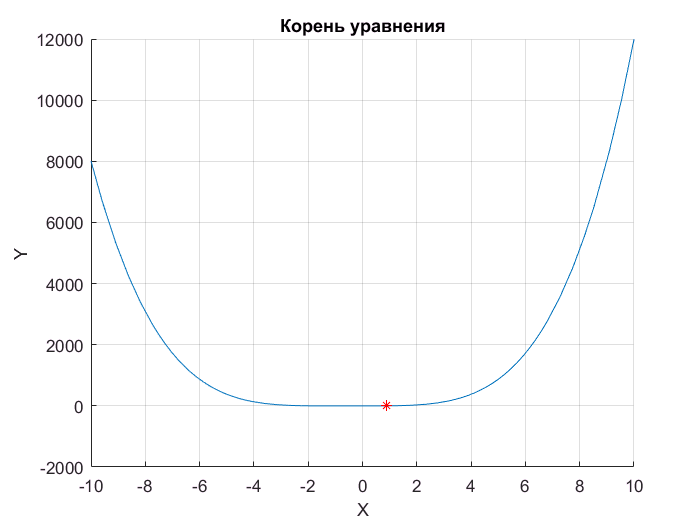

plot(x0, fun(x0), '*', 'Color', 'r');